[Iris dataset](https://en.wikipedia.org/wiki/Iris_flower_data_set) description

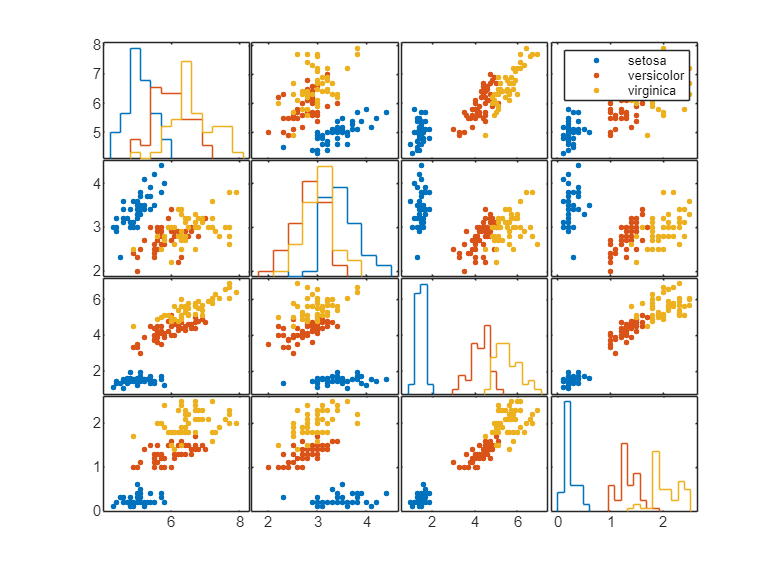

clearvars
close all
 
load fisheriris
gplotmatrix(meas,[],species)
grid on

%exportgraphics(gcf,"plotmatrix.pdf")

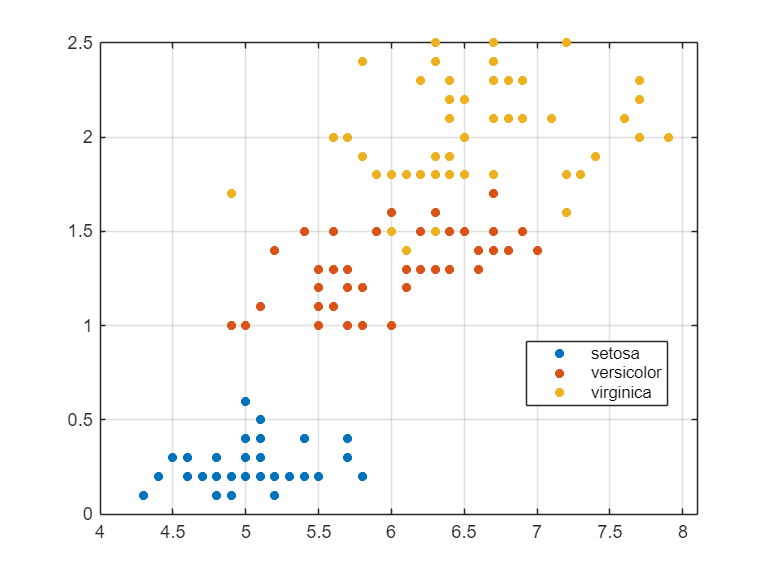

gscatter(meas(:,1),meas(:,4),categorical(species))
grid on

[coeff,score,latent,~,explained,mu] = pca(meas);

#### coeff

% coeff: transformation (or rotation) matrix

Contributions of each variable to the principal components

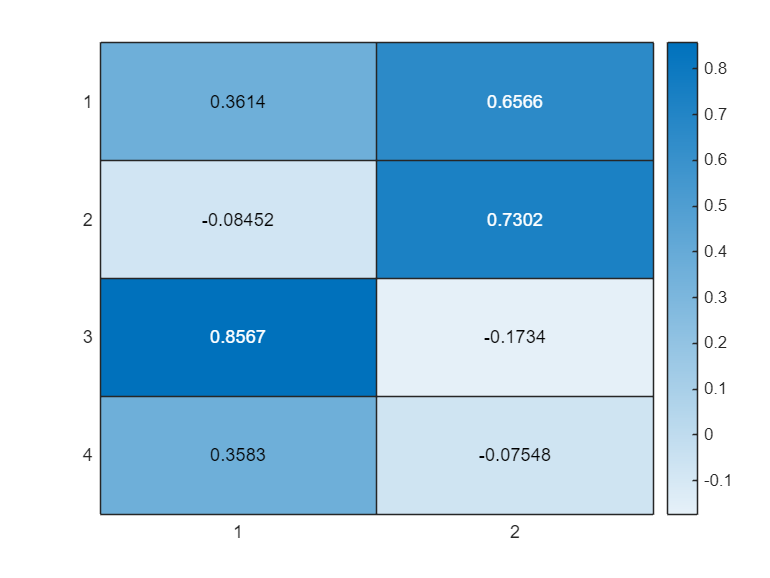

heatmap(coeff(:,1:2))

#### Score

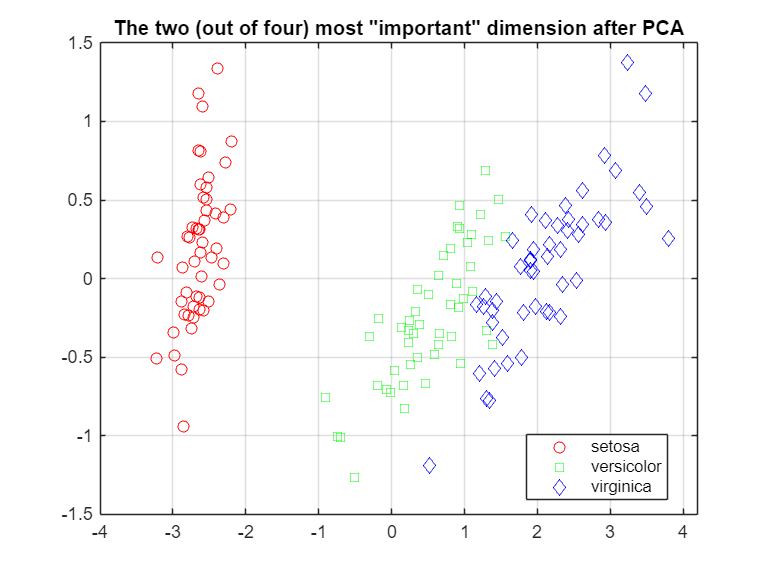

% score = (meas-mu)*coeff;
% score - transformed variables after the coordinate rotation
gscatter(score(:,1),score(:,2),species,'rgb','osd')
grid on
title('The two (out of four) most "important" dimension after PCA')

#### latent & explained

% eigenvalues
latent

latent =     4.2282
    0.2427
    0.0782
    0.0238


 principal component variances

explained

explained =    92.4619
    5.3066
    1.7103
    0.5212


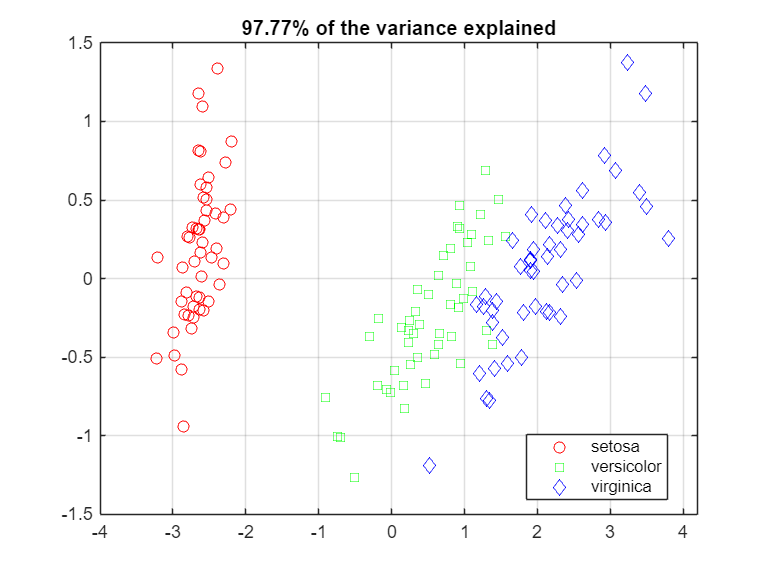

%explained = latent/sum(latent)*100
title([num2str(explained(1)+explained(2),4) '% of the variance explained'])

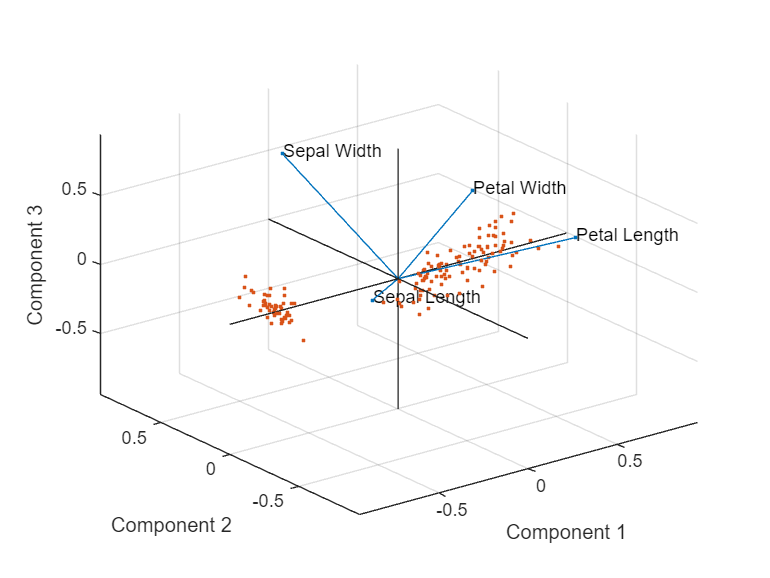

labels = {'Sepal Length','Sepal Width','Petal Length','Petal Width'};
biplot(coeff(:,1:3),'Scores',score(:,1:3),'VarLabels',labels)

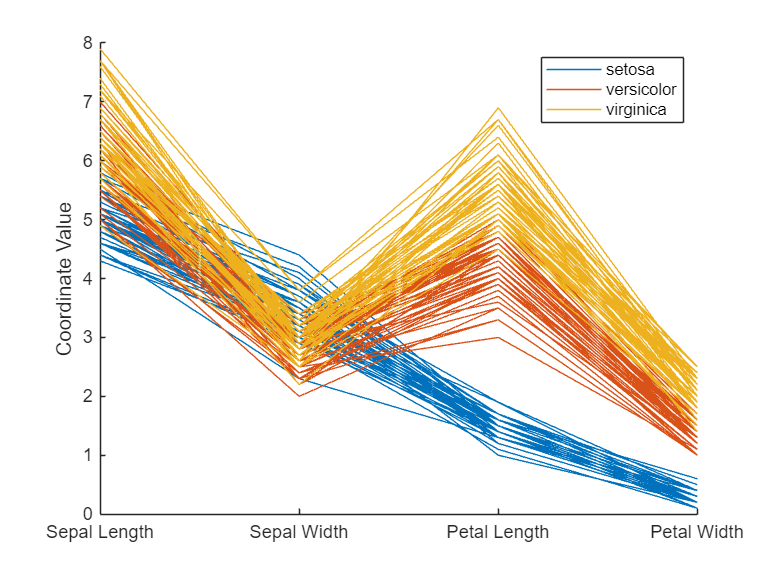

parallelcoords(meas,'Group',species,'Labels',labels)

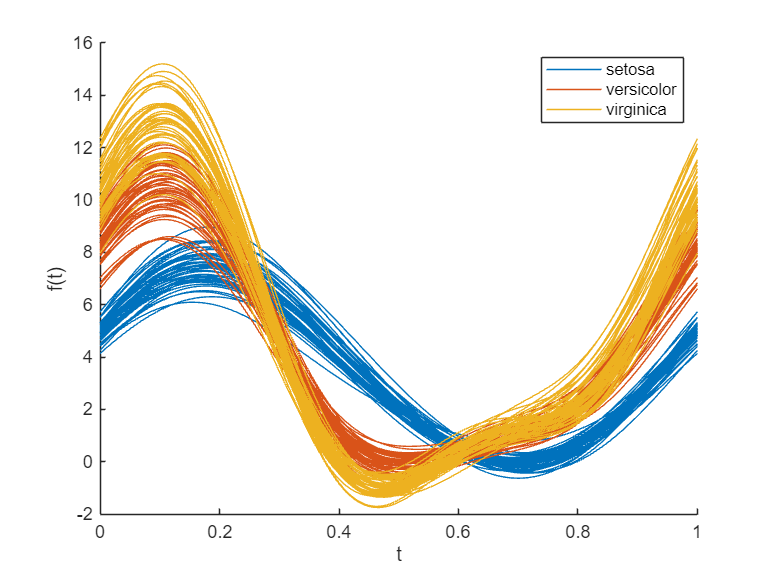

andrewsplot(meas,'group',species)